slm_res = 8; %um
slm_dim = [1080 1920]

slm_dim =         1080        1920



lens_size = 64;
pattern_size = floor(slm_dim/lens_size)

pattern_size =     16    30


redun_size = slm_dim - pattern_size*lens_size

redun_size =     56     0



offset = [10 10]

offset =     10    10



k0 = 2*pi/0.810

k0 = 7.7570

deflect_angle = deg2rad(0.5)

deflect_angle = 0.0087

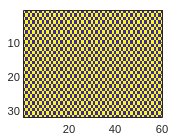


imagesc(kron(ones(pattern_size), [1 0; 0 1]))

base = zeros(pattern_size);
pattern = [1 1 1; 1 1 1; 1 1 1]

pattern =      1     1     1
     1     1     1
     1     1     1


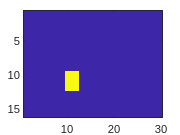


base(offset(1):offset(1)+size(pattern,1)-1, offset(2):offset(2)+size(pattern,2)-1) = pattern;
imagesc(abs(base))


lens_profile = four_control(base)

lens_profile =    0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 - 1.0000i
   0.0000 - 1.0000i   0.0000 + 1.0

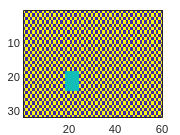

imagesc(angle(lens_profile))

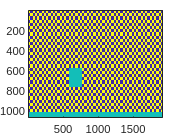


slm_profile = kron(lens_profile, ones(lens_size/2));
slm_profile = vertcat(slm_profile, zeros(redun_size(1,1),size(slm_profile,2)));
slm_profile = horzcat(slm_profile, zeros(redun_size(1,2),size(slm_profile,1)));

imagesc(angle(slm_profile))

function four_profile = four_control(profile)
    p1 = angle(profile) + acos(abs(profile));
    p2 = angle(profile) - acos(abs(profile));
        
    four_profile = zeros(2*size(profile));
    four_profile(1:2:size(four_profile,1), 1:2:size(four_profile,2)) = exp(1j*p1);
    four_profile(2:2:size(four_profile,1), 2:2:size(four_profile,2)) = exp(1j*p1);
    four_profile(2:2:size(four_profile,1), 1:2:size(four_profile,2)) = exp(1j*p2);
    four_profile(1:2:size(four_profile,1), 2:2:size(four_profile,2)) = exp(1j*p2);
end

function grad_profile = phase_gradient(base)
    
end